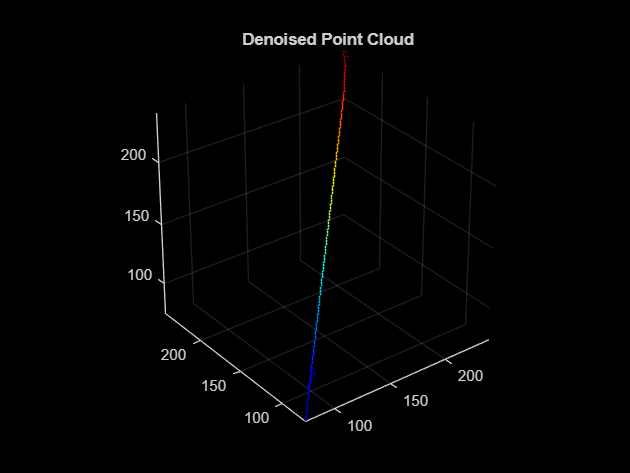

% 1. Load your data
load('380.mat', 'data'); 

% 2. Extract dimensions
x = data(:,:,:,1);
y = data(:,:,:,2);
z = data(:,:,:,3);
intensity = data(:,:,:,4);

% 3. Flatten data
x_flat = x(:);
y_flat = y(:);
z_flat = z(:);
intensity_flat = intensity(:);

% 4. Remove NaN/Inf values
valid_indices = ~isnan(x_flat) & ~isnan(y_flat) & ~isnan(z_flat) & ~isinf(x_flat) & ~isinf(y_flat) & ~isinf(z_flat);
x_clean = x_flat(valid_indices);
y_clean = y_flat(valid_indices);
z_clean = z_flat(valid_indices);
intensity_clean = intensity_flat(valid_indices);

% 5. Create the point cloud object (INITIAL visualization - grayscale)
ptCloud = pointCloud([x_clean, y_clean, z_clean], 'Intensity', intensity_clean);
figure; pcshow(ptCloud); title('Initial Point Cloud (Grayscale)');  % Grayscale by default
xlabel('X'); ylabel('Y'); zlabel('Z');
xlim([min(x_clean) max(x_clean)]); ylim([min(y_clean) max(y_clean)]); zlim([min(z_clean) max(z_clean)]);


% *** COLOR MAPPING (Corrected and in the right place) ***
% 1. Scale intensity to [0, 1]
min_intensity = min(intensity_clean);
max_intensity = max(intensity_clean);
scaled_intensity = (intensity_clean - min_intensity) / (max_intensity - min_intensity);

% 2. Choose colormap
colormap_name = 'jet';  % Or 'parula', 'hot', 'cool', 'gray', etc.
cmap = colormap(colormap_name);
num_colors = size(cmap, 1);

% 3. Apply colormap
ind = round(scaled_intensity * (num_colors - 1)) + 1;
ind(ind>num_colors)=num_colors; % prevent index out of range error
ind(ind<1)=1; % prevent index out of range error
rgb_colors = cmap(ind, :);

% 4. Set Color property of pointCloud object
ptCloud.Color = rgb_colors;

% 5. Visualize with color
figure; pcshow(ptCloud); title(['Colored Point Cloud (', colormap_name, ')']);
xlabel('X'); ylabel('Y'); zlabel('Z');
xlim([min(x_clean) max(x_clean)]); ylim([min(y_clean) max(y_clean)]); zlim([min(z_clean) max(z_clean)]);



% *** FURTHER PROCESSING EXAMPLES (Corrected) ***
% Downsampling
ptCloud_downsampled = pcdownsample(ptCloud, 'random', 0.1);
figure; pcshow(ptCloud_downsampled); title('Downsampled Point Cloud');

% Noise removal
ptCloud_denoised = pcdenoise(ptCloud);
figure; pcshow(ptCloud_denoised); title('Denoised Point Cloud');

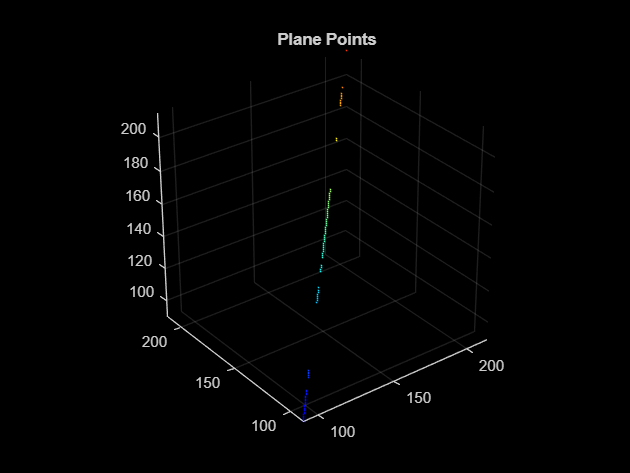


% Plane segmentation
% 1. Fit plane to the *cleaned* point cloud
[model,inliers] = pcfitplane(ptCloud,0.01); % 0.01 is the tolerance

% 2. Extract the points belonging to the plane
plane_points = select(ptCloud, inliers);  % Use ptCloud directly

% 3. Extract the remaining points (those NOT belonging to the plane)
remaining_indices = setdiff(1:ptCloud.Count, inliers); % Correct way to get remaining indices
remaining_points = select(ptCloud, remaining_indices);

% 4. Visualize
figure; pcshow(plane_points); title('Plane Points');

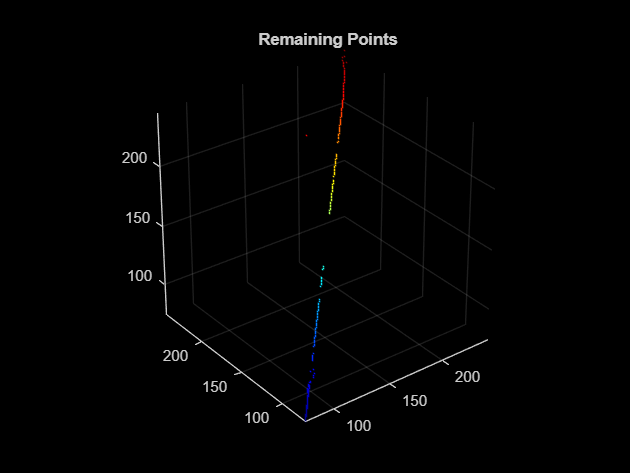

figure; pcshow(remaining_points); title('Remaining Points');